# Santos Port Throughput Analysis

## Overview

The Port of Santos is the largest in Latin America and plays a vital role in Brazil's trade and economy. Located in Santos, São Paulo state, it connects Brazil to more than 600 ports worldwide and is historically responsible for more than 25% of the international trade of the country. As a multipurpose complex, it handles a diverse range of cargo, including solid and liquid bulk, loose general cargo, containerized shipments, and project cargo, Consistently ranking among the top ports in national and international cargo movement analyses, the port set a new record in 2024 by handling nearly 5 million TEUs (twenty-foot equivalent unit). This upward trend in container throughput is expected to continue, driven by the steady growth of the global container market.

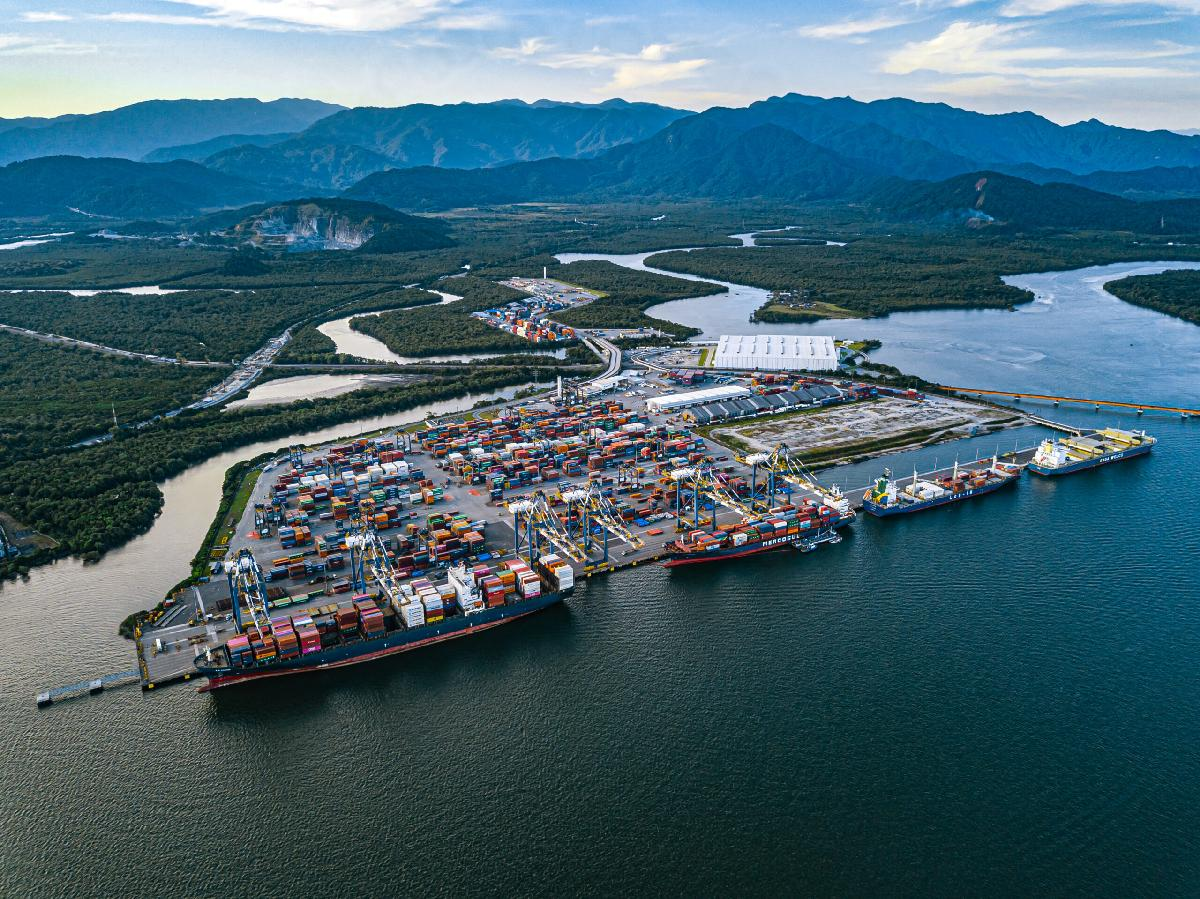

## Objective

This study aims to analyze the time series of container cargo throughput at the Port of Santos to identify trends, seasonality, and patterns in port activity. Additionally, the study aims to perform forecasting to predict future throughput and provide insights for terminals, shippers, authorities and other stakeholders. The dataset used is provided by the Santos Port Authority and is available for download on the organization's website.

## Import and Preprocessing the Data

% Clear workspace
clear
close
clc
warning("off")
format shortG

% Import the data
data = import_aps_data;

% Data overview
head(data)

      Ano        Mês         DESC_SIMPLES        TIPO_INSTALAÇÃO (grupos)       Terminal - GERIN             naturezacarga           TIPO_MOVIMENTO        navegacao        Sentido_carga           desc_spa          Toneladas    TEUs    Unidades
    ________    _____    ____________________    ________________________    _______________________    ________________________    ________________    _______________    _______________    ____________________    _________    ____    ________

    {'2025'}    {'1'}    {'I. BARNABE OESTE'}      {'PORTO ORGANIZADO

% Visualize the variable names and type
disp([data.Properties.VariableNames; data.Properties.VariableTypes]')

    "Ano"                         "cell"  
    "Mês"                         "cell"  
    "DESC_SIMPLES"                "cell"  
    "TIPO_INSTALAÇÃO (grupos)"    "cell"  
    "Terminal - GERIN"            "cell"  
    "naturezacarga"               "cell"  
    "TIPO_MOVIMENTO"              "cell"  
    "navegacao"                   "cell"  
    "Sentido_carga"               "cell"  
    "desc_spa"                    "cell"  
    "Toneladas"                   "double"
    "TEUs"                        "double"
    "Unidades"                    "double"



% Compute number of observations and columns
data_size = array2table(size(data), "VariableNames", ["no_of_observations" "no_of_columns"]);
disp(data_size)

    no_of_observations    no_of_columns
    __________________    _____________

        2.8842e+05             13      



`The dataset contains over 280,000 observations across 13 columns, including variables such as year, month, terminal, cargo type, units, weight, TEUs, and more.`

% Check the type of cargo
types_of_cargo = unique(data.naturezacarga)

types_of_cargo = 5×1 cell array
    {0×0 char              }
    {'CARGA CONTEINERIZADA'}
    {'CARGA GERAL'         }
    {'GRANEL LIQUIDO'      }
    {'GRANEL SOLIDO'       }


For the analysis, the dataset is filtered to focus specifically on container cargo by selecting rows where the *naturezadacarga* column is labeled as **CARGA CONTEINERIZADA**. This step excludes other cargo types, such as bulk or general cargo.

The data is then aggregated by year and month, and a time index is created in the timetable.

% Filter cargo type
container_data = data(data.naturezacarga == "CARGA CONTEINERIZADA", :);

% Summarizes the container data by year ("Ano") and month ("Mês")
monthly_data = groupsummary(container_data, ["Ano", "Mês"], "sum", "TEUs");
monthly_data = renamevars(monthly_data, "sum_TEUs", "TEUs");

% Create date variable from year and month columns
dates = datetime(str2double(monthly_data.Ano), str2double(monthly_data.("Mês")), 1);

% Create a timetable using dates as time indexes
full_series = table2timetable(monthly_data, 'RowTimes', dates);

% Remove unnecessary variables
full_series.Ano = [];
full_series.("Mês") = [];
full_series.GroupCount = [];

Now the dataset is sorted cronologically and it's investigated for regularity (no missing datas) and frequency.

% Sort data by Time
full_series = sortrows(full_series, "Time");

% Determine if input times are regular with respect to calendar unit (month)
[tf, dt] = isregular(full_series, "months")

tf = logical
   1


dt = calendarDuration
   1mo


% Compute time range of the dataset
time_span = [full_series.Properties.StartTime full_series.Time(end)]

time_span = 1×2 datetime array
   01-Jan-2005   01-Feb-2025


`The data spans January 2005 to February 2025, covering 242 months. It is regular (i.e., no months are missing) and sorted chronologically.`

% Visualyze the first and last rows of the train data
head(full_series)

       Time           TEUs   
    ___________    __________

    01-Jan-2005     1.686e+05
    01-Feb-2005    1.5497e+05
    01-Mar-2005    1.8672e+05
    01-Apr-2005    1.7257e+05
    01-May-2005    2.0218e+05
    01-Jun-2005    1.9235e+05
    01-Jul-2005    2.0301e+05
    01-Aug-2005    2.0998e+05



tail(full_series)

       Time           TEUs   
    ___________    __________

    01-Jul-2024    4.9269e+05
    01-Aug-2024    4.7679e+05
    01-Sep-2024    4.8364e+05
    01-Oct-2024    4.9373e+05
    01-Nov-2024     4.647e+05
    01-Dec-2024    4.7263e+05
    01-Jan-2025    4.6079e+05
    01-Feb-2025    4.3478e+05



The data preprocessing has been completed, and the dataset is now prepared for further analysis and modeling.

## Exploratory Analysis

### Understanding Trend and Seasonality

The figure below shows the run sequence plot of the time series, where the data reveals a noticeable trend with a consistent upward movement over time. Despite some fluctuations, the total TEUs handled at Santos demonstrate a clear long-term increase since 2005.

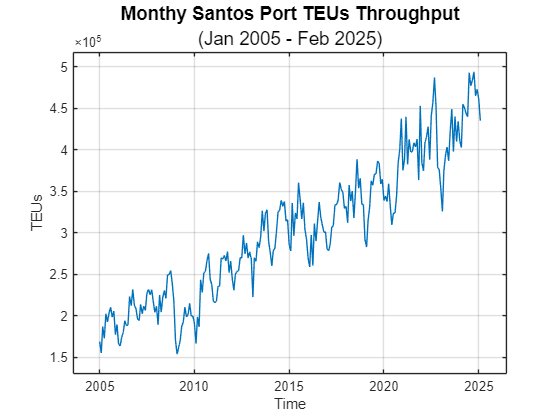

figure
plot(full_series, "Time", "TEUs")
title("Monthy Santos Port TEUs Throughput","(Jan 2005 - Feb 2025)", "FontSize", 14)
axis padded; grid on

The series possibly exhibit some seasonal pattern, with low activity at the beginning of the year and a peak in the second half. The boxplot below demonstrates how the number of TEUs is distributed across the months of the year.

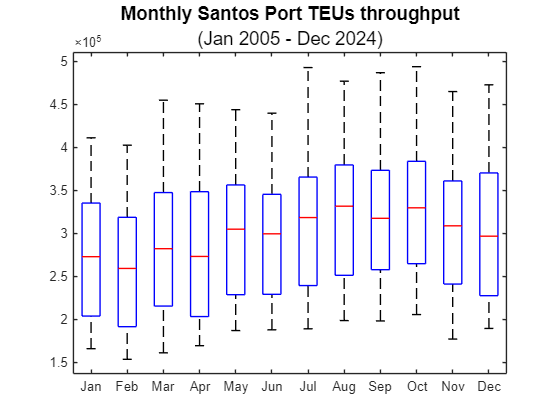

% Get only complete years
complete_years_series = full_series(year(full_series.Time) < 2025, :);

% Generate boxplot with the month labels
figure
month_labels = {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug', 'Sep', 'Oct', 'Nov', 'Dec'};
boxplot(complete_years_series.TEUs, complete_years_series.Time.Month, "Labels", month_labels)
title("Monthly Santos Port TEUs throughput","(Jan 2005 - Dec 2024)", "FontSize", 14)

Although the medians appear relatively stable and the spread of the boxplots is quite similar across months, some fluctuation in TEU volumes can be observed. To check for significant variation across the periods in the year, the Kruskal-Wallis test is applied to the detrended quarterly data,

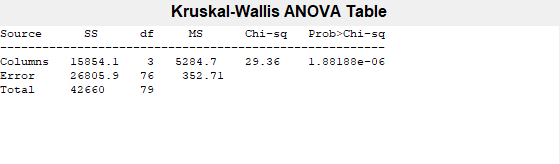

% Detrend the series
complete_years_series.detrended_TEUs = detrend(complete_years_series.TEUs);

% Transform quarters of year into columns
pivot_quarter = pivot(complete_years_series, Rows="Time", RowsBinMethod="year", Columns="Time", ...
    ColumnsBinMethod="quarterofyear", DataVariable="detrended_TEUs", Method="sum", ...
    RowLabelPlacement="rownames");
quarter_labels = {'Q1', 'Q2', 'Q3', 'Q4'};

% Performe Kruskal-Wallis test
[p, ~, stats] = kruskalwallis(table2array(pivot_quarter), quarter_labels);

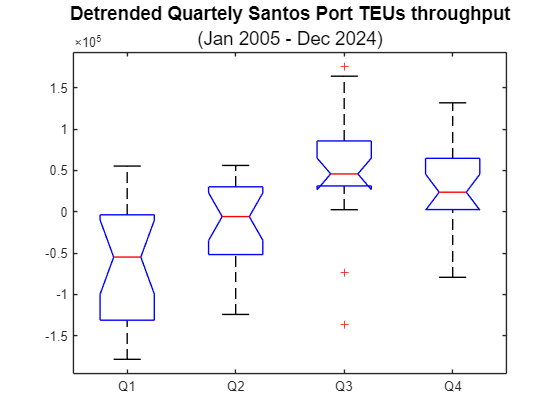

title("Detrended Quartely Santos Port TEUs throughput","(Jan 2005 - Dec 2024)", "FontSize", 14)

disp(p)

   1.8819e-06



The returned value of `p = 1.88e-06` indicates that Kruskal-Wallis rejects the null hypothesis that all data come from the same distribution at a 1% significance level. As expected, the beginning of the year shows a lower median volume, with the highest volumes concentrated in the second half. 

A follow-up test is conducted to identify which quarter comes from a different distribution

c = multcompare(stats);

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


% Display the multiple comparison results in a table.
multcompare_tbl = array2table(c, "VariableNames", ["Quarter A", "Quarter B", "Lower Limit", "A-B", "Upper Limit", "P-value"]);
disp(multcompare_tbl)

    Quarter A    Quarter B    Lower Limit     A-B      Upper Limit     P-value 
    _________    _________    ___________    ______    ___________    _________

        1            2          -32.128      -13.25       5.6285        0.27179
        1            3          -55.828      -36.95      -18.072      2.952e-06
        1            4          -46.678       -27.8      -8.9215      0.0008912
        2            3          -42.578       -23.7      -4.8215      0.0069005
        2            4          -33.428      -14.55       4.3285         0.1955
        3            4          -9.7285        9.15       28.028        0.59801



The results indicate a significant difference between quarters 1 and 3, as well as between quarters 1 and 4, since their p-values are below 0.05. This suggests that the test rejects the null hypothesis, meaning the data in these groups likely come from different distributions. Similarly, the test also rejects the null hypothesis for quarters 2 and 3, indicating a significant difference between these groups. However, there is no significant difference between quarters 1 and 2, quarters 2 and 4, or quarters 3 and 4, as their p-values are above 0.05.

A comparison of the mean ranks across quarter is plotted below.

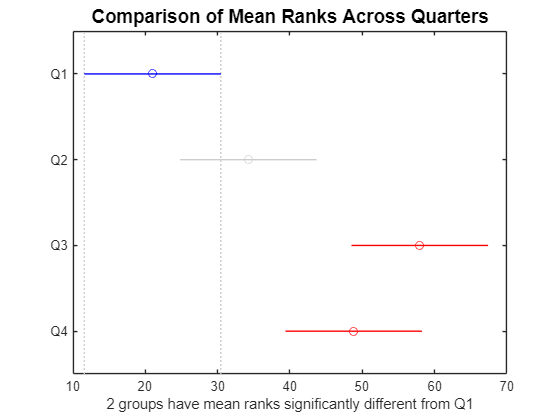

title("Comparison of Mean Ranks Across Quarters", "FontSize", 14)

### Understanding Variability

Another important characteristic to verify is the heterocedasticity, which refers to the changing level of variability across different values of the series. To explore this further, the relationship between the mean and the standard deviation is plotted below.

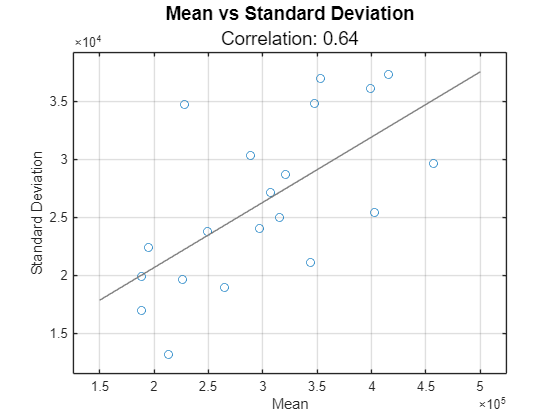

% Group the series yearly
yearly_series = groupsummary(complete_years_series, "Time", "year", ["sum","mean","std"], "TEUs");
yearly_series.GroupCount = [];

% Create the scatter plot
figure
scatter(yearly_series, "mean_TEUs", "std_TEUs")
lsline
title("Mean vs Standard Deviation", sprintf('Correlation: %.2f', corr(yearly_series.mean_TEUs,yearly_series.std_TEUs)), "FontSize", 14)
box on; grid on; axis padded
xlabel("Mean"); ylabel("Standard Deviation")

As seen, a clear positive correlation between the mean and the standard deviation is evident, indicating that as the mean increases, so does the variability of the data. This relationship suggests that in periods of higher throughput, fluctuations are more pronounced.

## Data Transformation

Trends and changes in variability indicate non-stationarity in the time series, which can affect analysis and predictive models. To address this, it is necessary to transform the data appropriately. These transformations aim to stabilize the variance and bring the time series closer to stationarity. Additionally, it is important to decompose the time series to identify and separate the trend and periodicity components, allowing for more accurate data analysis.

All transformations performed will be reversed later to ensure accurate predictions and maintain interpretability.

### Addressing Heteroscedasticity

To address the heteroscedasticity identified in the data, we will apply a logarithmic transformation, as there is a positive correlation between mean and the standard deviations in the yearly TEUs volume.

% Create log-transformed series column
complete_years_series.log_TEUs = log(complete_years_series.TEUs);

% Compare the data range before and after the logarithmic transformation
original_range = [min(complete_years_series.TEUs), max(complete_years_series.TEUs)]

original_range =       153409      493727


transformed_range = [min(complete_years_series.log_TEUs), max(complete_years_series.log_TEUs)]

transformed_range =        11.941        13.11


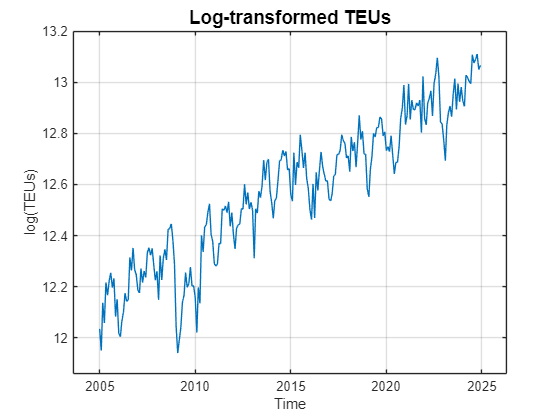

% Visualize the transformed data
figure;
plot(complete_years_series.Time, complete_years_series.log_TEUs);
title("Log-transformed TEUs", "FontSize", 14);
xlabel("Time"); ylabel("log(TEUs)");
axis padded; grid on;

Let's visually compare the mean and standard deviation of the original and the transformed data. 

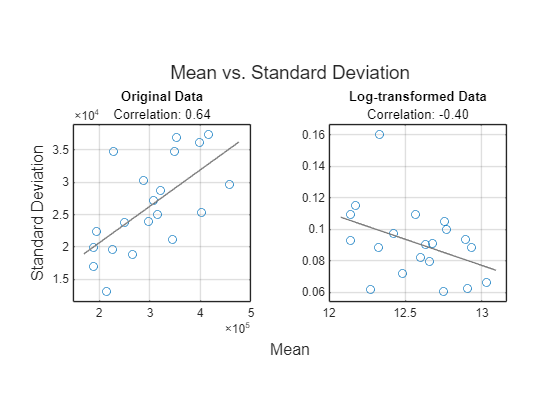

% Group series yearly with TEUs and log_TEUs
yearly_series = groupsummary(complete_years_series, "Time", "year", ["sum","mean","std"], ["TEUs","log_TEUs"]);

% Plot mean vs standard deviation of the original and the log-transformed series
figure
t = tiledlayout(1,2);
title(t,"Mean vs. Standard Deviation", "FontSize", 14)
xlabel(t, "Mean")
ylabel(t, "Standard Deviation")

% Generate plot for mean vs standard of the original series
nexttile
scatter(yearly_series, "mean_TEUs", "std_TEUs")
title("Original Data")
subtitle(sprintf('Correlation: %.2f', corr(yearly_series.mean_TEUs, yearly_series.std_TEUs)))
grid on; box on; axis square padded
xlabel(''); ylabel('')
lsline

% Generate plot for mean vs standard of the log-transformed series
nexttile
scatter(yearly_series, "mean_log_TEUs", "std_log_TEUs")
title("Log-transformed Data")
subtitle(sprintf('Correlation: %.2f', corr(yearly_series.mean_log_TEUs, yearly_series.std_log_TEUs)))
grid on; box on
xlabel(''); ylabel('')
axis padded square
lsline

The log-transformed series exhibits a weaker correlation between its mean and standard deviation compared to the original series, indicating that it is closer to homoscedasticity. Therefore, the transformed data will be used for modeling.

### Splitting Series into Train and Test Sets

Data up to December 2023 will be used for training the models, while data from 2024 onward will be reserved for testing.

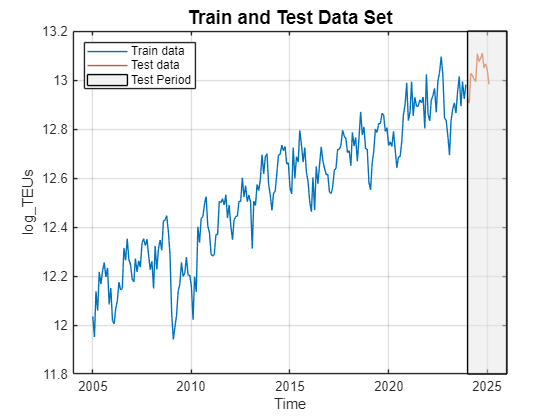

% Create log_teus column in the full series
full_series.log_TEUs = log(full_series.TEUs);

% Split the dataset
train_data = full_series(year(full_series.Time) <= 2023, :);
test_data = full_series(year(full_series.Time) > 2023, :);

% Plot the series
figure
plot(train_data, "Time", "log_TEUs")
hold on
plot(test_data,"Time", "log_TEUs")

% Highlight test period
px = datetime({'01-Jan-2024', '01-Jan-2026', '01-Jan-2026', '01-Jan-2024'});
py = [11.8 11.8 13.2 13.2];
hf = patch(px, py, [0.9 0.9 0.9], "FaceAlpha", 0.5);

% Plot Setup
ylim([11.8 13.2]); xlim(datetime({'01-Jan-2004' '01-Jan-2026'}))
grid on
legend(["Train data", "Test data", "Test Period"], "Location", "northwest")
title("Train and Test Data Set", "FontSize", 14)

### Time Series Decomposition

Breaking down a time series into its fundamental components is essential for understanding underlying patterns and improving forecasting accuracy. These components include:

- Long-term trend -- The overall direction of the data over time;

- Seasonal component -- Reccuring patterns or cycles that repeat at regular intervals;

- Residual component -- The remaining variatios after removing trend and seasonality.

By isolating these elements, a clearer interpretation of the data is achieved, facilitating more precise predictions.

% Decompose the series
[LT, ST, R] = trenddecomp(train_data.log_TEUs, "NumSeasonal", 1);

% Create table trends
trends = array2timetable([LT,ST,R], "VariableNames", ["long_term","seasonal","remainder"], "RowTimes", train_data.Time);

 The charts below show all the components isolated, as well as the log-transformed series.

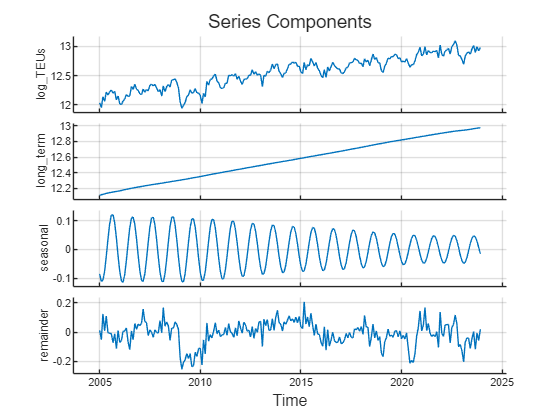

% Plot the components
figure
t = tiledlayout("vertical");
t.TileSpacing = "compact";
title(t,"Series Components", "FontSize", 14)
xlabel(t, "Time");

% Log-transformed series
nexttile
plot(train_data, "Time", "log_TEUs")
set(gca, "XTickLabels", [])
axis padded; box off; grid on; xlabel([])

% Long-term
nexttile
plot(trends, "Time", "long_term")
set(gca, "XTickLabels", [])
axis padded; box off; grid on; xlabel([])

% Seasonal
nexttile
plot(trends, "Time", "seasonal")
set(gca, "XTickLabels", [])
axis padded; box off; grid on; xlabel([])

% Remainder
nexttile
plot(trends, "Time", "remainder")
axis padded; box off; grid on; xlabel([])

Once different modeling approaches will be used for the components and the remainder, let's create a separate table only for the remaining time series.

% Create remaining series table
remaining_series = timetable(trends.Time, trends.remainder, VariableNames="remainder");

## Modeling the Components

### Long-Term and Seasonal Components

The long-term component approximates a linear trend and will therefore be modeled as a first-degree polynomial in the form $P\left(x\right)=p_1 x+p_2$

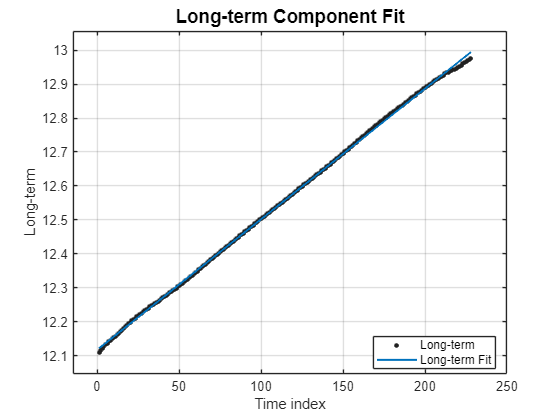

[long_term_mdl, long_term_gof] = createLongTermFit(trends.long_term);
title("Long-term Component Fit", "FontSize", 14)
legend(["Long-term","Long-term Fit"], "Location", "best")
xlabel("Time index"); ylabel("Long-term")
axis padded; grid on

disp(long_term_gof)

           sse: 0.0052654
       rsquare: 0.99964
           dfe: 226
    adjrsquare: 0.99964
          rmse: 0.0048268



The seasonal component exhibits periodic behavior and will therefore be modeled as the sum of two sine terms to capture its cyclic patterns in the form$S\left(x\right)=a_1 \sin \left(b_1 x+c_1 \right)+a_2 \sin \left(b_2 x+c_2 \right)$

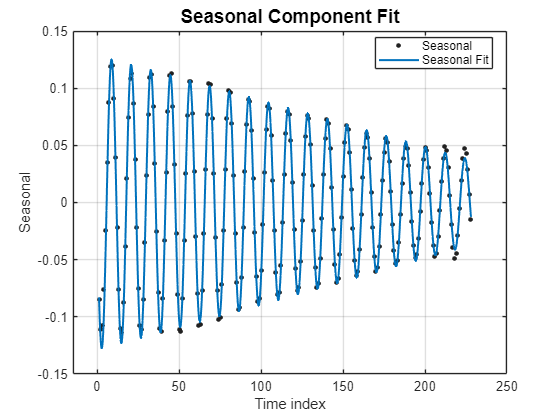

[seasonal_mdl, seasonal_gof] = createSeasonalFit(trends.seasonal);
title("Seasonal Component Fit", "FontSize", 14)
legend(["Seasonal","Seasonal Fit"], "Location", "best")
xlabel("Time index"); ylabel("Seasonal")
axis padded; grid on

disp(seasonal_gof)

           sse: 0.0016987
       rsquare: 0.99806
           dfe: 222
    adjrsquare: 0.99801
          rmse: 0.0027662



Both models appear to fit the data well, as indicated by the goodness-of-fit metrics.

The next step is to analyze the remaining data by applying statistical models to capture residual patterns not explained by these components, further enhancing the forecasting accuracy.

### Residual Component

#### Stationarity Tests

The augmented Dickey–Fuller (ADF) test checks for the presence of a unit root in the time series. Its null hypothesis states that the series has a unit root, meaning it is non-stationary. The Kwiatkowski–Phillips–Schmidt–Shin (KPSS) test, on the other hand, assesses whether a time series is trend-stationary. Its null hypothesis states that the series is stationary. Using both tests together can provide stronger evidence regarding stationarity. If the ADF test rejects non-stationarity while the KPSS test does not reject stationarity, the series is likely to be stationary.

% Check for a unit root with ADF test
disp(adftest(remaining_series))

                h      pValue     stat      cValue     Lags    Alpha    Model      Test 
              _____    ______    _______    _______    ____    _____    ______    ______

    Test 1    true     0.001     -7.8876    -1.9421     0      0.05     {'AR'}    {'T1'}



% Check for a trend with KPSS test
disp(kpsstest(remaining_series, "Trend", false))

                h       pValue      stat     cValue    Lags    Alpha    Trend
              _____    ________    ______    ______    ____    _____    _____

    Test 1    true     0.041171    0.5022    0.463      0      0.05     false



The results of the ADF and KPSS tests are conflicting: the ADF test suggests stationarity by rejecting its null hypothesis, while the KPSS test indicates non-stationarity by failing to reject its null hypothesis. To resolve this, I will apply additional transformations, specifically differentiation, to remove trends and stabilize the variance. After these transformations, I will reapply the KPSS test to reassess the stationarity of the series.

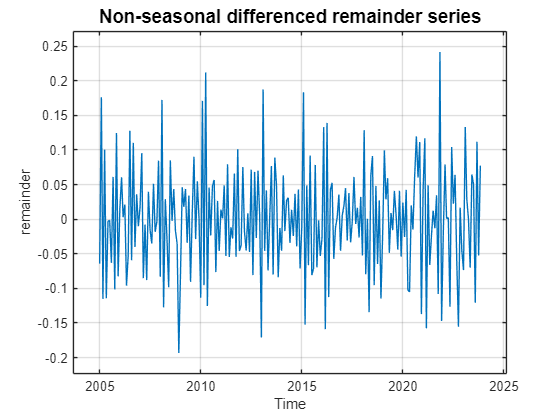

% Non-seasonal differenced
non_seasonal_differenced = diff(remaining_series);

% Plot the non-seasonal differenced series
figure
plot(non_seasonal_differenced, "Time", "remainder")
title("Non-seasonal differenced remainder series", "FontSize", 14)
axis padded; grid on

% Apply KPSS test on the differenced series
disp(kpsstest(non_seasonal_differenced, "Trend", false))

                h      pValue      stat       cValue    Lags    Alpha    Trend
              _____    ______    _________    ______    ____    _____    _____

    Test 1    false     0.1      0.0055442    0.463      0      0.05     false



The result indicates stationarity, providing clear evidence that the series no longer exhibits a unit root. This confirms that a single differentiation was sufficient to achieve stationarity, identifying the parameter `d = 1` for an ARIMA model.

I will now proceed to analyze the autocorrelation function (ACF) and partial autocorrelation function (PACF) plots to determine the appropriate autoregressive (AR) and moving average (MA) terms.

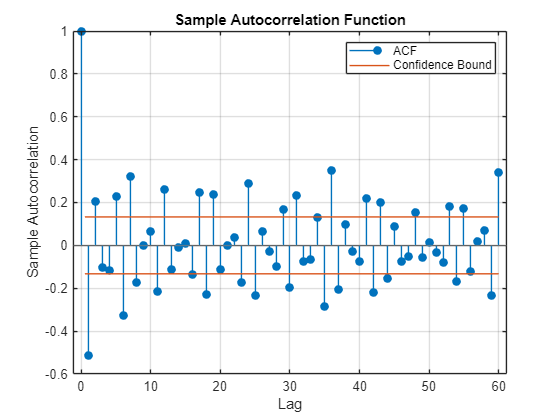

% Plot autocorrelation function
figure
autocorr(non_seasonal_differenced, "NumLags", 60)

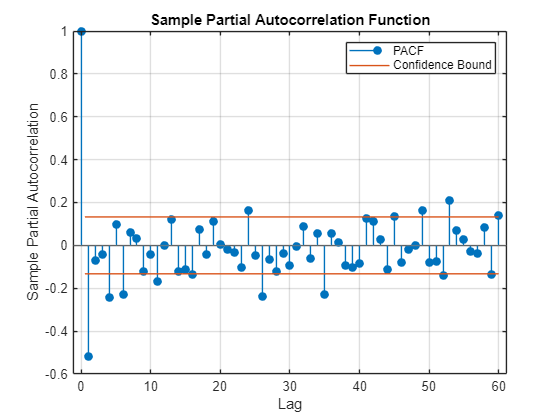

% Plot partial autocorrelation function
figure
parcorr(non_seasonal_differenced, "NumLags", 60)

The significant negative spikes at lag 1 in both the ACF and PACF suggest that both AR(1) and MA(1) terms should be considered in the initial model specification. The presence of several other significant spikes in the ACF indicates that a higher-order MA component might be needed.

#### Model Selection and Training

To keep it simple, a starter **ARIMA(1,1,1)** model will be used as a reference, and I will gradually increase its complexity.

% Establish reference ARIMA(1,1,1) model
starter = struct();
starter.mdl = arima("Constant", 0, "ARLags", 1, "D", 1, "MALags", 1);
starter.est = estimate(starter.mdl, remaining_series);

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant            0              0           NaN             NaN
    AR{1}        -0.34063        0.12278       -2.7742       0.0055339
    MA{1}        -0.23539        0.11577       -2.0333        0.042019
    Variance    0.0042626     0.00035099        12.144      6.1426e-34



% Stater model summary stats
starter.summary = summarize(starter.est);
disp(starter.summary)

               Description: "ARIMA(1,1,1) Model (Gaussian Distribution)"
                SampleSize: 228
    NumEstimatedParameters: 3
             LogLikelihood: 298.68
                       AIC: -591.36
                       BIC: -581.07
                     Table: [4×4 table]
             VarianceTable: [1×4 table]



% Previous index
prev_idx = height(train_data)

prev_idx =    228


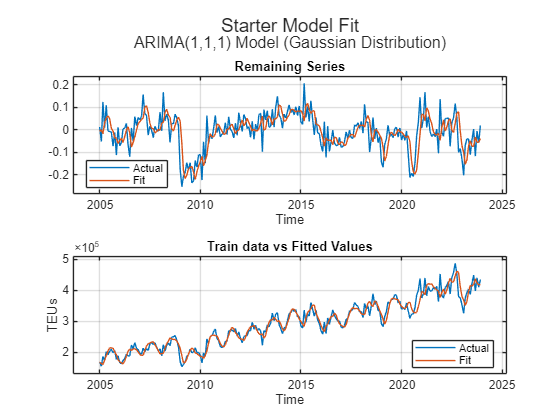

% Create table for reference model fit
starter.fit = table();
starter.fit.Time = remaining_series.Time;
starter.fit.residuals = infer(starter.est, remaining_series.remainder); % compute models residuals
starter.fit.y_hat = remaining_series.remainder - starter.fit.residuals; % compute models fit
starter.fit.sum = (starter.fit.y_hat) + feval(long_term_mdl, 1:prev_idx) + feval(seasonal_mdl, 1:prev_idx); % sum of series components
starter.fit.TEUs = exp(starter.fit.sum); % reverse log-transformation

% Visualize the fitted values
figure
t = tiledlayout;
title(t, "Starter Model Fit", "FontSize", 14)
subtitle(t, starter.mdl.Description)

% Remaining series
nexttile
plot(remaining_series, "Time", "remainder")
hold on
plot(starter.fit, "Time", "y_hat")
title("Remaining Series")
axis padded; grid on
legend("Actual", "Fit", "Location", "best")

% Train data vs fitted reference model
nexttile
plot(train_data, "Time", "TEUs")
hold on
plot(starter.fit, "Time", "TEUs")
title("Train data vs Fitted Values")
grid on; axis padded
legend("Actual", "Fit", "Location", "best")

Let's now compute some metrics to verify how good the model perfoms on the train data set.

starter.fit_metrics = computeMetrics(starter.fit.TEUs, train_data.TEUs);
disp(starter.fit_metrics)

       MSE         MAE     RMSE      MAPE      RRSE  
    __________    _____    _____    ______    _______

    4.0931e+08    14897    20231    5.0746    0.26469



The `MAPE = 5.07%` suggests good relative accuracy, and the `RRSE = 0.26` indicates the model performs significantly better than a naive predictor. Additionally, the `RMSE = 20,231` provides a meaningful measure of the absolute error, expressed in the same units as the original data.

Given the clear seasonal patterns observed in the ACF and PACF plots, as highlighted by significant recurring spikes, it is appropriate to proceed with a **seasonal ARIMA (SARIMA)** model to better capture this structure.

% Estabilish sarima model
sarima_spike = struct();
sarima_spike.mdl = arima("Constant", 0, "ARLags", 1, "D", 1, "MALags", 1:2, "SARLags", [12 24 36], "Seasonality", 0, "SMALags", [12 24 36 48 60]);
sarima_spike.est = estimate(sarima_spike.mdl, remaining_series);

 
    ARIMA(1,1,2) Model with Seasonal AR(36) and MA(60) (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant            0              0            NaN            NaN
    AR{1}         -0.5889        0.38004        -1.5496        0.12125
    SAR{12}       0.47937       0.096774         4.9535     7.2897e-07
    SAR{24}      -0.31156         0.1057        -2.9475       0.003203
    SAR{36}       0.77036        0.05747         13.405     5.6783e-41
    MA{1}         0.20851        0.39022        0.53435         0.5931
    MA{2}       -0.079877        0.16607       -0.48097        0.63054
    SMA{12} <

% sarima_spike model summary stats
sarima_spike.summary = summarize(sarima_spike.est);
disp(sarima_spike.summary)

               Description: "ARIMA(1,1,2) Model with Seasonal AR(36) and MA(60) (Gaussian Distribution)"
                SampleSize: 228
    NumEstimatedParameters: 12
             LogLikelihood: 340.13
                       AIC: -656.26
                       BIC: -615.11
                     Table: [13×4 table]
             VarianceTable: [1×4 table]



Now let's try a seasonal differencing on the series and analyse its ACF and PACF.

To start off, we Create the lag operator polynomials $1-L$ and $1-L^2$. Then, multiply them to get the desired lag operator polynomial.

D1 = LagOp({1 -1}, 'Lags', [0 1]);
D12 = LagOp({1 -1}, 'Lags', [0 12]);
D = D1 * D12

D =     1-D Lag Operator Polynomial:
    -----------------------------
        Coefficients: [1 -1 -1 1]
                Lags: [0 1 12 13]
              Degree: 13
           Dimension: 1

Filter the data with differencing polynomial `D` to get the nonseasonally and seasonally differenced series.

diff_remaining_series = filter(D, remaining_series.remainder);

% Calculate the loss of observations compared to the original remaining series
l = length(remaining_series.remainder) - length(diff_remaining_series)

l =     13


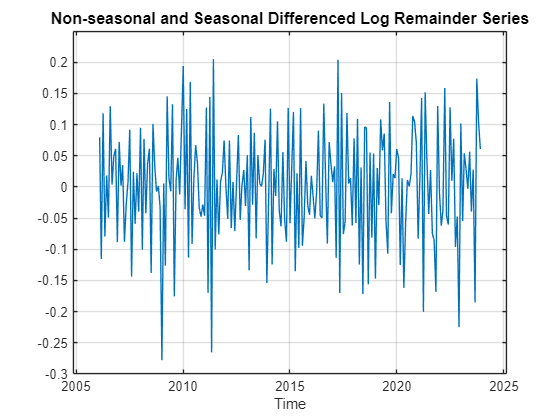

% Plot the non-seasonal and seasonal differenced series
figure
plot(remaining_series.Time(l+1:end), diff_remaining_series)
title('Non-seasonal and Seasonal Differenced Log Remainder Series', 'FontSize', 12)
axis padded; grid on; xlabel("Time")

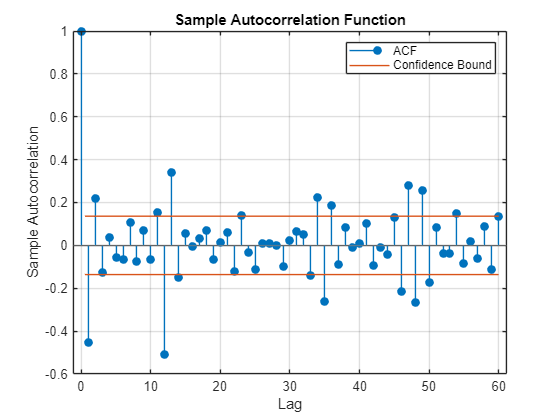

% Plot ACF
figure
autocorr(diff_remaining_series, "NumLags", 60)

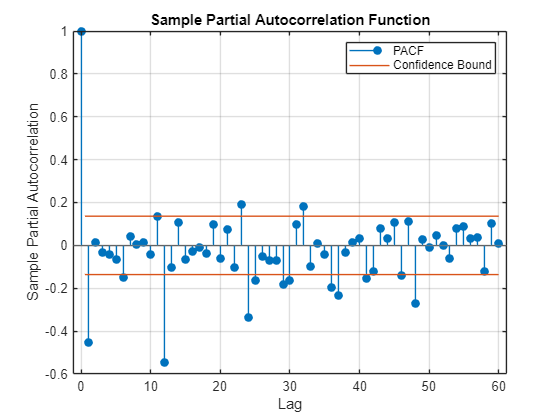

% Plot PACF
figure
parcorr(diff_remaining_series, "NumLags", 60)

Although fewer lags show significant correlation compared to the non-seasonally differenced series, the **ACF** and **PACF** plots of the seasonally and non-seasonally differenced series still exhibit a complex pattern. To try to capture this behavior, we will now test a SARIMA model that incorporates seasonal differencing and extended lags up to the third order for the non-seasonal parameters. This model is specified as **SARIMA(3,1,3)(3,1,5)[12]** and will be referred to as `sarima_extended`.

sarima_extended = struct();
sarima_extended.mdl = arima("Constant", 0, "ARLags", 1:3, "D", 1, "MALags", 1:3, "SARLags", [12 24 36], "Seasonality", 12, "SMALags", [12 24 36 48 60]);
sarima_extended.est = estimate(sarima_extended.mdl, remaining_series);

 
    ARIMA(3,1,3) Model Seasonally Integrated with Seasonal AR(36) and MA(60) (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant            0              0            NaN             NaN
    AR{1}         0.71411        0.36724         1.9445        0.051835
    AR{2}         0.28861        0.07879          3.663       0.0002493
    AR{3}        -0.18846        0.20249       -0.93069         0.35201
    SAR{12}      -0.86484       0.076116        -11.362      6.4484e-30
    SAR{24}      -0.79183       0.068009        -11.643       2.489e-31
    SAR{36}      -0.78883        0.03428        -23.012     3.

% sarima_extended model summary stats
sarima_extended.summary = summarize(sarima_extended.est);
disp(sarima_extended.summary)

               Description: "ARIMA(3,1,3) Model Seasonally Integrated with Seasonal AR(36) and MA(60) (Gaussian Distribution)"
                SampleSize: 228
    NumEstimatedParameters: 15
             LogLikelihood: 353.17
                       AIC: -676.34
                       BIC: -624.9
                     Table: [16×4 table]
             VarianceTable: [1×4 table]



The model `sarima_extended` shows an even better fit, as it has the lowest AIC and BIC among all models. Now, let's evaluate their performance on the test dataset to assess their predictive power.

% Reverse the log-transformation
test_data.TEUs = exp(test_data.log_TEUs);
train_data.TEUs = exp(train_data.log_TEUs);

% Forecast indexes
frcst_idx = (prev_idx+1:prev_idx + height(test_data))';

% Forecast horizon
frcst_horizon = height(frcst_idx)

frcst_horizon =     14


% Evaluate these models at the specified indices
long_term_frcst = feval(long_term_mdl, frcst_idx);
seasonal_frcst = feval(seasonal_mdl, frcst_idx);

We will now forecast the remaining time series with the models

% stater model
starter.frcst = table();
starter.frcst.Time = test_data.Time;
[starter.frcst.frcst, starter.frcst.residuals] = forecast(starter.est, frcst_horizon, remaining_series.remainder);

To create the final forecast, we add the individual results from each model component: the long-term, seasonal, and ARIMA models. This approach combines all aspects of the time series data for a complete prediction.

starter.frcst.sum = long_term_frcst + seasonal_frcst + starter.frcst.frcst;

To make our forecast interpretable, we need to reverse the initial transformation. We used a logarithmic function to stabilize the data, and now we'll apply the exponential function to return the data to its original scale. This ensures our forecasted values match the units of the observed data, making the forecasts accurate and useful for decision-making

starter.frcst.TEUs = exp(starter.frcst.sum);

Let's do the same for the `sarima_spike` and `sarima_extended`

% sarima_spike model
sarima_spike.frcst = table();
sarima_spike.frcst.Time = test_data.Time;
[sarima_spike.frcst.frcst, sarima_spike.frcst.residuals] = forecast(sarima_spike.est, frcst_horizon, remaining_series.remainder);
sarima_spike.frcst.sum = long_term_frcst + seasonal_frcst + sarima_spike.frcst.frcst;
sarima_spike.frcst.TEUs = exp(sarima_spike.frcst.sum);

% sarima_extended model
sarima_extended.frcst = table();
sarima_extended.frcst.Time = test_data.Time;
[sarima_extended.frcst.frcst, sarima_extended.frcst.residuals] = forecast(sarima_extended.est, frcst_horizon, remaining_series.remainder);
sarima_extended.frcst.sum = long_term_frcst + seasonal_frcst + sarima_extended.frcst.frcst;
sarima_extended.frcst.TEUs = exp(sarima_extended.frcst.sum);

Here we plot the actual TEUs data from the test period alongside our forecasted values

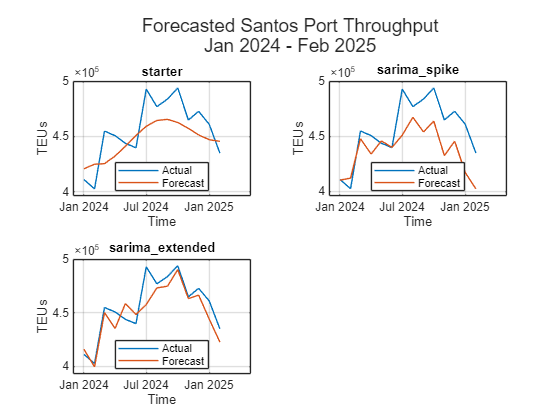

figure
t = tiledlayout("flow");
title(t, "Forecasted Santos Port Throughput", "Jan 2024 - Feb 2025", "FontSize", 14)

% stater model
nexttile
plot(test_data, "Time", "TEUs")
hold on
plot(starter.frcst, "Time", "TEUs")
title("starter")
ylabel("TEUs"); grid on; axis padded
legend("Actual", "Forecast", "Location", "best")

% sarima_spike model
nexttile
plot(test_data, "Time", "TEUs")
hold on
plot(sarima_spike.frcst, "Time", "TEUs")
title("sarima\_spike")
ylabel("TEUs"); grid on; axis padded
legend("Actual", "Forecast", "Location", "best")

% sarima_extended model
nexttile
plot(test_data, "Time", "TEUs")
hold on
plot(sarima_extended.frcst, "Time", "TEUs")
title("sarima\_extended")
ylabel("TEUs"); grid on; axis padded
legend("Actual", "Forecast", "Location", "best")

The plots above show that all of the three models understimate the mid-2024 peak. The starter model Tends to **smooth out variability**, missing some fluctuation patterns while the `sarima_spike's `Forecast values seem more conservative. The `sarima_extended` Model is the best fit of the three, as it **follows the actual trend closely**.

To evaluate the models more objectively, we now compute a set of performance metrics.

% Compute performance metrics on the test data set
starter.frcst_metrics = computeMetrics(starter.frcst.TEUs, test_data.TEUs);
sarima_spike.frcst_metrics = computeMetrics(sarima_spike.frcst.TEUs, test_data.TEUs);
sarima_extended.frcst_metrics = computeMetrics(sarima_extended.frcst.TEUs, test_data.TEUs);

% Combine metrics in one table
metrics = [starter.frcst_metrics; sarima_spike.frcst_metrics; sarima_extended.frcst_metrics];
metrics.Properties.RowNames = {'ARIMA(1,1,1)', 'SARIMA(1,1,2)(3,0,5)[12]', 'SARIMA(3,1,3)(3,1,5)[12]'};
disp(metrics)

                                   MSE         MAE     RMSE      MAPE      RRSE  
                                __________    _____    _____    ______    _______

    ARIMA(1,1,1)                3.8187e+08    17349    19542    3.7708    0.72587
    SARIMA(1,1,2)(3,0,5)[12]    6.2728e+08    20210    25045    4.3334    0.93031
    SARIMA(3,1,3)(3,1,5)[12]    1.7251e+08    10023    13134    2.1741    0.48788



The **SARIMA(3,1,3)(3,1,5)[12]** model (`sarima_extended`) outperforms the all the other model across all evaluation metrics. It presents:

- Lower **AIC** and **BIC** indicate better model fit with a balance between goodness-of-fit and complexity;

- Higher** Log-likelihood** that `sarima_extended` explains the training data better`;`

- Lower **MSE**, **MAE**, and **RMSE** suggest that `sarima_extended` makes smaller prediction errors;

- Lower **MAPE** shows it's relatively more accurate in percentage terms;

- Lower **RRSE** demonstrates that `sarima_extended` performs better than a simple mean predictor baseline.

The **SARIMA(3,1,3)(3,1,5)[12]** model (`sarima_extended`) is the **most reliable** and should be the go-to model for forecasting Santos Port TEUs, as It demonstrates both **strongest trend fitting** and **lowest forecast error.**

Next, we visualize the complete time series along with the forecasted values and their respective confidence intervals.

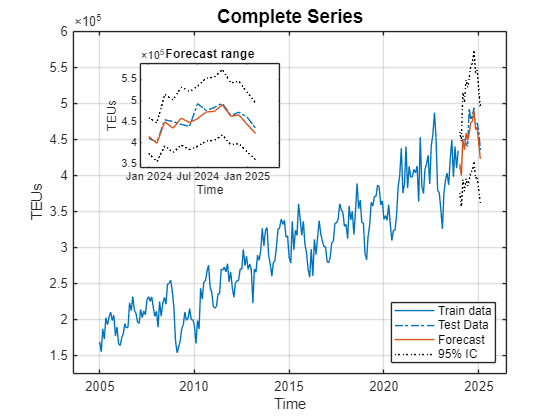

% Compute 95% cofidence bounds
Z = 1.96; % Z-Score for 95%
[sarima_extended.frcst.lower_ci_95, sarima_extended.frcst.upper_ci_95] = computeCI(sarima_extended.frcst, long_term_mdl, seasonal_mdl, frcst_idx, Z);

% Plot the series
figure
plot(train_data, "Time", "TEUs")
title("Complete Series", "FontSize", 14)
axis padded
hold on
plot(test_data, "Time", "TEUs", "Color", "#0072BD", "LineStyle", "-.");
plot(sarima_extended.frcst, "Time", "TEUs", "Color", "#D95319")
plot(sarima_extended.frcst, "Time", "lower_ci_95", "Color", "k", "LineStyle", ":")
plot(sarima_extended.frcst, "Time", "upper_ci_95", "Color", "k", "LineStyle", ":")
legend(["Train data","Test Data","Forecast","95% IC"], "Location", "southeast")
ylabel("TEUs"); grid on

% Create inset axes
inset_pos = [0.25 0.6 0.25 0.25];
axes('Position', inset_pos)
plot(test_data,"Time","TEUs","LineStyle","-.");
title("Forecast range")
hold on
plot(sarima_extended.frcst, "Time","TEUs")
plot(sarima_extended.frcst, "Time", "lower_ci_95", "Color", "k", "LineStyle", ":")
plot(sarima_extended.frcst, "Time", "upper_ci_95", "Color", "k", "LineStyle", ":")
ylabel("TEUs"); axis padded

#### Residuals Analysis

To confirm the model's adequacy, we now examine the **residuals** to ensure they are randomly distributed and free of autocorrelation—key signs that the model has captured the underlying structure of the data. We begin with a visual inspection, followed by statistical tests to validate residual behavior.

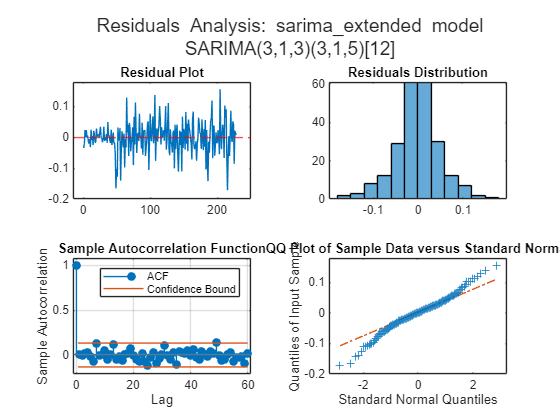

% Create table for sarima_extended model fit
sarima_extended.fit = table();
sarima_extended.fit.Time = remaining_series.Time;
sarima_extended.fit.residuals = infer(sarima_extended.est, remaining_series.remainder); % compute models residuals
sarima_extended.fit.y_hat = remaining_series.remainder - sarima_extended.fit.residuals; % compute models fit
sarima_extended.fit.sum = (sarima_extended.fit.y_hat) + feval(long_term_mdl, 1:prev_idx) + feval(seasonal_mdl, 1:prev_idx); % sum of series components
sarima_extended.fit.TEUs = exp(sarima_extended.fit.sum); % reverse log-transformation

% Create tiled layout
figure
t = tiledlayout(2,2);
title(t, "Residuals Analysis: sarima\_extended model", "FontSize", 14)
subtitle(t, "SARIMA(3,1,3)(3,1,5)[12]", "FontSize", 14)

% Plot residuals
nexttile
plot(sarima_extended.fit.residuals)
axis padded
yline(0,"Color","r","LineStyle","--")
title("Residual Plot")

% Plot residuals histogram
nexttile
histogram(sarima_extended.fit.residuals)
title("Residuals Distribution")

% Plot residuals ACF
nexttile
autocorr(sarima_extended.fit.residuals,"NumLags",60)
axis padded

% Plot residuals qq-plot
nexttile
qqplot(sarima_extended.fit.residuals)
box on; axis padded

The charts above indicate that the residuals appear to follow a normal distribution and show no clear signs of autocorrelation.

Let's now plot the residuals against the fitted value and look for correlation:

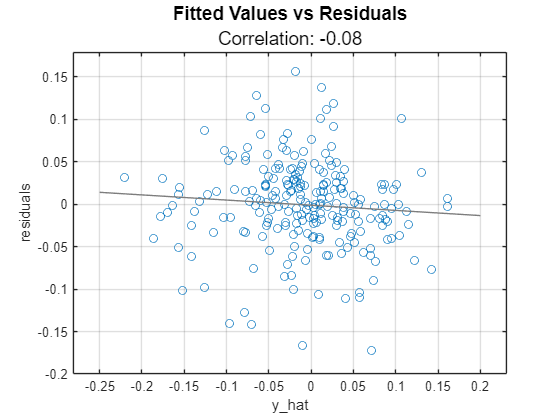

figure
scatter(sarima_extended.fit, "y_hat", "residuals")
title("Fitted Values vs Residuals", sprintf('Correlation: %.2f',corr(sarima_extended.fit.y_hat, sarima_extended.fit.residuals)), "FontSize", 14)
lsline
box on; grid on; axis padded

The correlation of `corr = -0.08` between residuals and fitted values is extremely low, suggesting minimal linear dependence and reinforcing the assumption of homoscedasticity.

By performining a **Lujung-Box test** we can assess whether the residuals exhibit autocorrelation:

% Lujung-Box test
disp(lbqtest(sarima_extended.fit.residuals, "DataVariable", "Y_Residual", "Lags", 60))

   0



Since the test result was false, it means that the test failed to reject the null hypothesis,i.e.the residuals do not show significant autocorrelation and model  produces residuals that behave like white noise, therefore our model effectively captures the time series pattern.

## Forecasting Data

Once the model was select

We can now compare the yearly cumulative actual TEUs with the forecasted data.

% Group the data yearly
yearly_test_data = (groupsummary(test_data, "Time", "year", "sum", "TEUs"));
yearly_forecast_data = (groupsummary(sarima_extended.frcst, "Time", "year", "sum", "TEUs"));
test_vs_forecast = join(yearly_test_data, yearly_forecast_data, "Keys", "year_Time", "LeftVariables", ["year_Time","sum_TEUs"], "RightVariables", "sum_TEUs");
test_vs_forecast.percent_error = test_vs_forecast.sum_TEUs_yearly_forecast_data ./ test_vs_forecast.sum_TEUs_yearly_test_data - 1;
disp(test_vs_forecast)

    year_Time    sum_TEUs_yearly_test_data    sum_TEUs_yearly_forecast_data    percent_error
    _________    _________________________    _____________________________    _____________

      2024               5.486e+06                      5.431e+06                -0.010042  
      2025              8.9557e+05                     8.6621e+05                -0.032778  



The forecasted TEUs closely matched the actual observed values, 1% difference in the amount for 2024 and a 3% underestimation in the first 2025 bimester.

Now, let's examine how the model forecasts data for the next 10 years, up to December 2024.

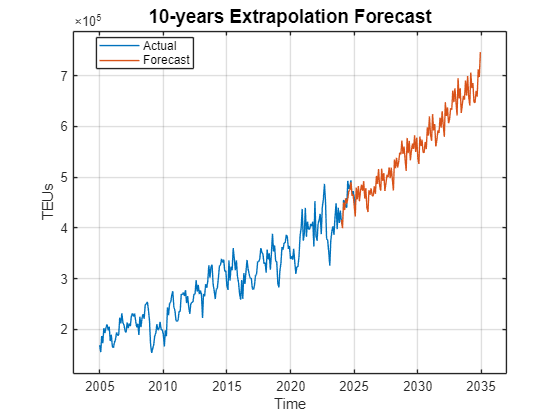

% Set the new forecast horizon
start_date = datetime(2024, 1, 1);
end_date = datetime(2034, 12, 1);
date_vector = start_date:calmonths(1):end_date;
new_horizon = length(date_vector);
new_horizon_idx = prev_idx+1:prev_idx+new_horizon;

% Data forecast
long_term_forecast = feval(long_term_mdl, new_horizon_idx);
seasonal_forecast = feval(seasonal_mdl, new_horizon_idx);
remaining_forecast = forecast(sarima_extended.est, new_horizon, remaining_series.remainder);

% Sum of components
components_sum = long_term_forecast + seasonal_forecast + remaining_forecast;

% Reverse log transformation
forecasted_TEUs = exp(components_sum);

% Plot the data
figure
plot(full_series, "Time", "TEUs")
hold on
plot(date_vector, forecasted_TEUs)
axis padded
legend(["Actual", "Forecast"], Location="best")
title("10-years Extrapolation Forecast", "FontSize", 14)
grid on

Let's now see the annual throughput and how it evolves over the year by ploty the sum of TEUs moved in Santos per year.

yearly_grouped_TEUs = table();
yearly_grouped_TEUs.Time = date_vector';
yearly_grouped_TEUs.forecasted_TEUs = forecasted_TEUs;
yearly_grouped_TEUs = groupsummary(yearly_grouped_TEUs, "Time", "year", "sum","forecasted_TEUs");
disp(yearly_grouped_TEUs)

    year_Time    GroupCount    sum_forecasted_TEUs
    _________    __________    ___________________

      2024           12             5.431e+06     
      2025           12            5.5963e+06     
      2026           12            5.6684e+06     
      2027           12            5.9744e+06     
      2028           12            6.3795e+06     
      2029           12            6.6617e+06     
      2030           12            6.8013e+06     
      2031           12            7.1341e+06     
      2032           12            7.5723e+06     
      2033           12            7.9283e+06     
      2034           12            8.1467e+06     



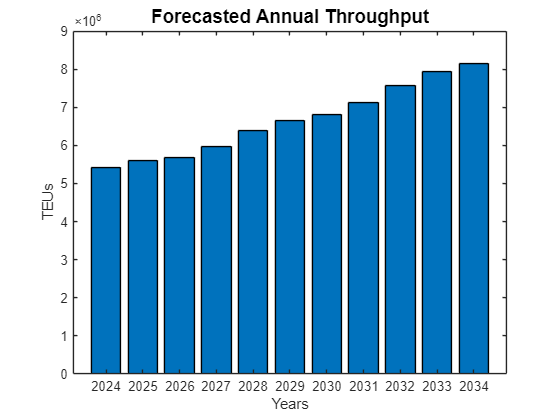

figure
bar(yearly_grouped_TEUs.year_Time, yearly_grouped_TEUs.sum_forecasted_TEUs)
title("Forecasted Annual Throughput", "FontSize", 14)
xlabel("Years"); ylabel("TEUs")

% Compute CAGR
no_of_periods = double(max(yearly_grouped_TEUs.year_Time)) - double(min(yearly_grouped_TEUs.year_Time))

no_of_periods =     10


cagr = (yearly_grouped_TEUs(end, "sum_forecasted_TEUs") ./ yearly_grouped_TEUs(1, "sum_forecasted_TEUs")) .^ (1 / no_of_periods) - 1;
cagr = renamevars(cagr,"sum_forecasted_TEUs", "CAGR");
disp(cagr)

      CAGR  
    ________

    0.041383



## Conclusions and Future Analysis

This study applies statistical methods to forecast the movement of TEUs at the Port of Santos. A public dataset provided by the Santos Port Authority, which includes historical data dating back to 2005, was used for the analysis. An exploratory data analysis (EDA) was conducted to understand the data, followed by necessary transformations to prepare it for forecasting.  ARIMA and SARIMA models were tested, with the SARIMA(3,1,3)(3,1,5)[12] model yielding the best fit. This model demonstrated excellent performance on test data, achieving a mean absolute percentage error (MAPE) of 2.1%.

A 10-year extrapolation was also conducted, revealing that the Port of Santos is expected to handle approximately 5.6 million TEUs in 2025, with an increase to 8.1 million TEUs by 2034. This growth corresponds to a compound annual growth rate (CAGR) of 4.1%. However, achieving this forecast will require significant investments in terminal infrastructure, as the current capacity is approaching saturation.

For future analysis, models incorporating exogenous variables, such as macroeconomic indicators and geopolitical factors, could be explored to improve the robustness of the forecasts.